clear all


t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



M = [1 -2 1; -2 2 0; 1 0 0]

M =      1    -2     1
    -2     2     0
     1     0     0



T = (t.^linspace(2,0,3))'

T =          0    0.0001    0.0004    0.0009    0.0016    0.0025    0.0036    0.0049    0.0064    0.0081    0.0100    0.0121    0.0144    0.0169    0.0196    0.0225    0.0256    0.0289    0.0324    0.0361    0.0400    0.0441    0.0484    0.0529    0.0576    0.0625    0.0676    0.0729    0.0784    0.0841    0.0900    0.0961    0.1024    0.1089    0.1156    0.1225    0.1296    0.1369    0.1444    0.1521    0.1600    0.1681    0.1764    0.1849    0.1936    0.2025    0.2116    0.2209    0.2304    0.2401
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0

P=[2,-10,4]

P =      2   -10     4


M*T

ans =     1.0000    0.9801    0.9604    0.9409    0.9216    0.9025    0.8836    0.8649    0.8464    0.8281    0.8100    0.7921    0.7744    0.7569    0.7396    0.7225    0.7056    0.6889    0.6724    0.6561    0.6400    0.6241    0.6084    0.5929    0.5776    0.5625    0.5476    0.5329    0.5184    0.5041    0.4900    0.4761    0.4624    0.4489    0.4356    0.4225    0.4096    0.3969    0.3844    0.3721    0.3600    0.3481    0.3364    0.3249    0.3136    0.3025    0.2916    0.2809    0.2704    0.2601
         0    0.0198    0.0392    0.0582    0.0768    0.0950    0.1128    0.1302    0.1472    0.1638    0.1800    0.1958    0.2112    0.2262    0.2408    0.2550    0.2688    0.2822    0.2952    0.3078    0.3200    0.3318    0.3432    0.3542    0.3648    0.3750    0.3848    0.3942    0.4032    0.4118    0.4200    0.4278    0.4352    0.4422    0.4488    0.4550    0.4608    0.4662    0.4712    0.4758    0.4800    0.4838    0.4872    0.4902    0.4928    0.4950    0.4968    0.4982    0.4992   

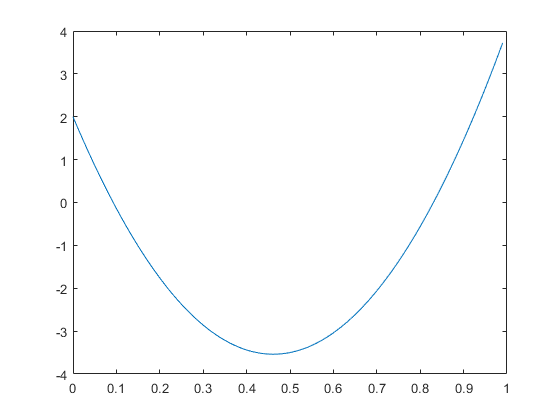

plot(t,P(1:3)*M*T)


splinez = []


splinez =

     []



t2 = 0

t2 = 0

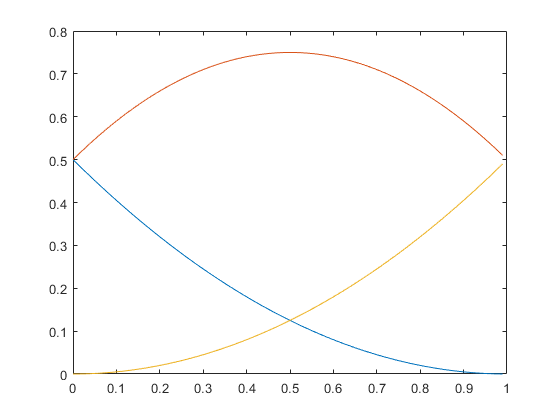


T = (t.^linspace(2,0,3))';

% t=0.5
N0 = 0.5*((t-t2).^2-2*(t-t2)+1);
N1 = 0.5*(-2*(t-t2).^2+2*(t-t2)+1);
N2 = 0.5*(t-t2).^2;

plot(t,N0)
hold on
plot(t,N1)
plot(t,N2)
hold off


% P=[4,-1,2]
spline = []


spline =

     []



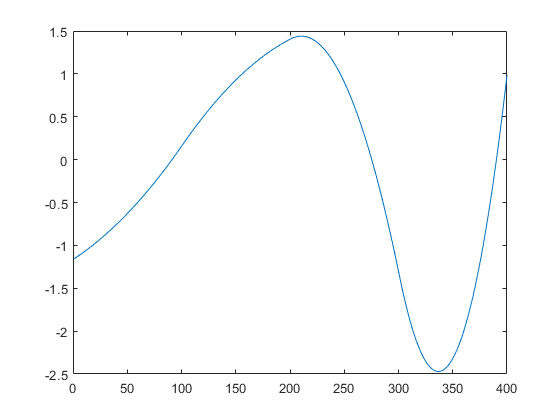

for j = 1:(length(P)-2)
   spline = [spline ;[N0 N1 N2]*P(j:j+2)]; 
    
end

plot(spline)


T'*M'

ans =     1.0000         0         0
    0.9801    0.0198    0.0001
    0.9604    0.0392    0.0004
    0.9409    0.0582    0.0009
    0.9216    0.0768    0.0016
    0.9025    0.0950    0.0025
    0.8836    0.1128    0.0036
    0.8649    0.1302    0.0049
    0.8464    0.1472    0.0064
    0.8281    0.1638    0.0081



M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

% 
% 
% splinez = [splinez ; T'*M'*P(1:3)'];
% 
% plot(splinez)

N=[]


N =

     []




knots = 4

knots = 4

knotdist = 1/knots

knotdist = 0.2500

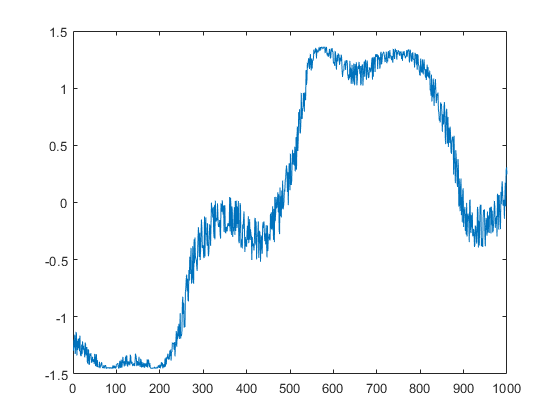


input = rand(1000,1);
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output);
[B,I] = sort(input);
plot(output(I))


for i=1:length(input)
   index(i)= floor(input(i)/knotdist)+1;
   N(i,index(i):index(i)+2) = (mod(input(i),knotdist)/(knotdist)).^linspace(2,0,3)*M';
end

P=pinv(N)*output

P =    -0.8128
   -1.6759
   -0.3756
    1.4938
    0.9004
   -2.0321




spline = []


spline =

     []



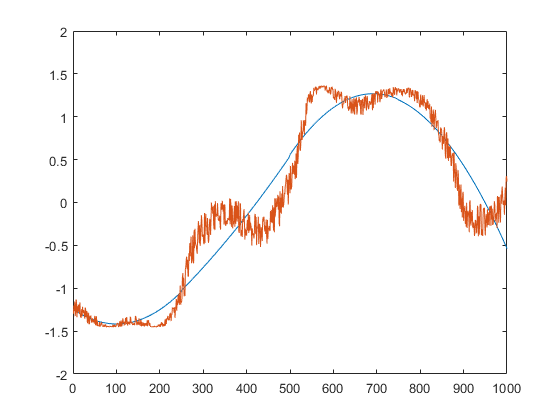

for j = 1:(length(P)-2)
   spline = [spline(1:end-1) ;[N0 N1 N2]*P(j:j+2)]; 
end

plot(linspace(0,1000,length(spline)),spline)
hold on
plot(1:length(output),output(I))
% y = N*P
axis([0 1000 -2 2])
% plot(y(I))
% plot(linspace(0,1000,length(P)),P)
hold off


y = N*P

plot(y(I))



index= [];
N=[];
B =t

B =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


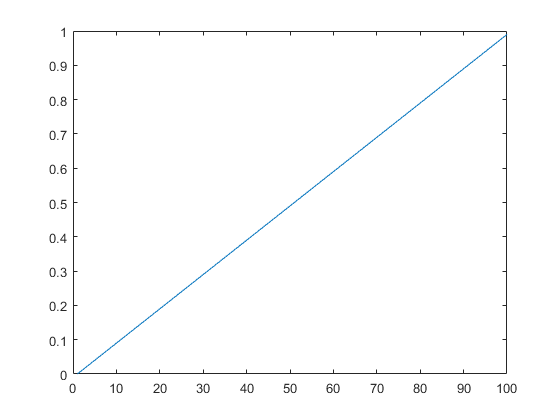

output = sin(exp(B)+sin(10*B).^2+3*cos(3*B)+0.3*rand(100,1));

plot(B)

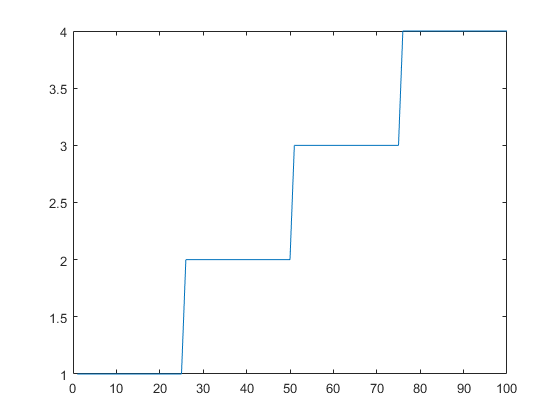


for i=1:length(B)
   index(i)= floor(B(i)/knotdist)+1;
   N(i,index(i):index(i)+2) = (mod(B(i),knotdist)/(knotdist)).^linspace(2,0,3)*M';
end

plot(index)


P=pinv(N)*output

P =    -0.5249
   -1.1742
   -0.2253
    1.1117
    0.6254
   -1.3641



y=N*P

y =    -0.8495
   -0.8742
   -0.8963
   -0.9159
   -0.9329
   -0.9474
   -0.9593
   -0.9687
   -0.9755
   -0.9797


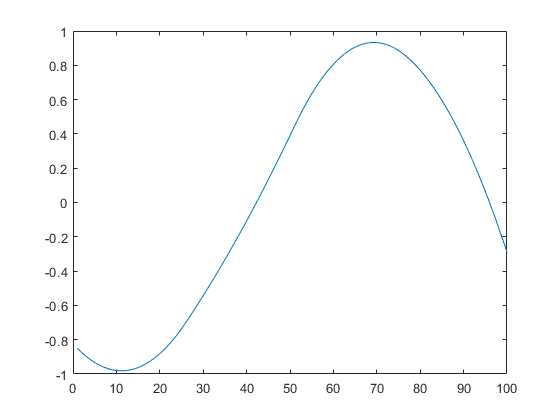


plot(y)

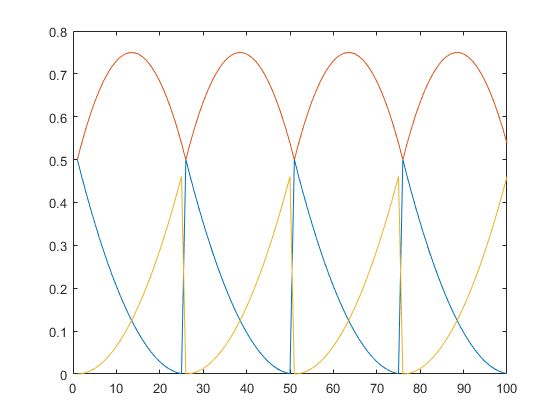


plot((mod(B,knotdist)/(knotdist)).^linspace(2,0,3)*M')